# Importing Data from Excel Spreadsheets

MATLAB provides you with the tools to import spreadsheet data both interactively and programmatically. To interactively import spreadsheet data, see [docid:import_export.br81u9o](docid:import_export.br81u9o). This example shows how to import data programmatically using `readtable` and `spreadsheetDatastore`.

- Use `readtable` when your data resides in a worksheet of an Excel® spreadsheet file.

- Use `spreadsheetDatastore` when your data resides in multiple sheets of a spreadsheet file or in a collection of multiple spreadsheet files.

Data used for this example comes from USA domestic airline flights between 1996 and 2008. The information is organized in an Excel® file with multiple sheets, where each sheet contains data for 1 year. Download the full data set from [http://stat-computing.org/dataexpo/2009/the-data.html](http://stat-computing.org/dataexpo/2009/the-data.html).

## Import Spreadsheet Data as Table

Spreadsheets contain data structured as columns of numbers and text. The MATLAB® `table` data type provides a natural way of working with such column-oriented heterogeneous data. You can use tables to store variable names or row names along with the data in a single container.

Use the `readtable` function to import data from a spreadsheet into a table. The resulting table, `airlinedata`, contains one variable for each column in the spreadsheet. By default, `readtable` treats the data in the first row of the file as the variable names.

airlinedata = readtable('airlinesmall_subset.xlsx');

## Import Subset of Data

When you want to import only a portion of the data from the spreadsheet, call the `readtable` function with the `Range` name-value pair. The value for the `Range` name-value pair specifies the subset of rows and columns to be imported.

airlinedata = readtable('airlinesmall_subset.xlsx','Range','A1:F10');

## Import from Specific Worksheet

By default, `readtable` reads data from the first worksheet. However, the `Sheet` name-value pair lets you specify which worksheet to read from. For instance, the data in this example is organized by worksheet by year. Import the data from a specific worksheet by using the name-value pair argument to specify the worksheet name.

airlinedata = readtable('airlinesmall_subset.xlsx','Sheet','2008');

## Represent Variables in Table with MATLAB Data Types

During the import process, `readtable` detects whether the data is text or numeric. However, to leverage the additional functionality offered by MATLAB® native data types, you may choose to convert the data types of the variables. For instance, converting variables with date and time information to `datetime` lets you perform efficient computations, comparisons, and formatted display of dates and times.

Create a smaller table with only the variables to be converted, by specifying the variable names.

data = airlinedata(:,{'Year','Month','DayofMonth','UniqueCarrier','ArrDelay'});
data(1:5,:)

ans =     Year    Month    DayofMonth    UniqueCarrier    ArrDelay
    ____    _____    __________    _____________    ________

    2008    1        3             'WN'               1     
    2008    1        4             'WN'              -4     
    2008    1        6             'WN'              22     
    2008    1        7             'WN'              24     
    2008    1        8             'WN'             -17     


`readtable` imports the first three variables (columns), `Year`, `Month`, and `DayofMonth`, as numeric data containing date information. The fourth variable `UniqueCarrier` is imported as text, which contains repeated labels. Finally, the fifth variable `ArrDelay` is imported as numeric data, which contains duration information.

Represent `Year`, `Month` and `DayofMonth` as type `datetime`, the `UniqueCarrier` as `categorical`, and `ArrDelay` as `duration` in minutes.

data.Date = datetime(data.Year,data.Month,data.DayofMonth); % Columns 1 through 3
data.UniqueCarrier = categorical(data.UniqueCarrier);
data.ArrDelay = minutes(data.ArrDelay);

## Import Data from Collection of Spreadsheets

A `datastore` is useful for processing arbitrarily large amounts of data that are spread across multiple files. Both data import and data processing can be performed through the datastore.

Create a `datastore` from a collection of spreadsheets in `airlinesmall_subset.xlsx` and preview the contents.

ds = spreadsheetDatastore('airlinesmall_subset.xlsx');
p = preview(ds);
p(:,1:7)

ans =     Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime
    ____    _____    __________    _________    _______    __________    _______

    1996    1        18            4            2117       2120          2305   
    1996    1        12            5            1252       1245          1511   
    1996    1        16            2            1441       1445          1708   
    1996    1         1            1            2258       2300          2336   
    1996    1         4            4            1814       1814          1901   
    1996    1        31            3            1822       1820          1934   
    1996    1        18            4             729        730           841   
    1996    1        26            5            1704       1705          1829   


Select the variables to import by specifying variable names.

ds.SelectedVariableNames = {'Year','Month','DayofMonth','UniqueCarrier','ArrDelay'};

To leverage the additional functionality of MATLAB® native data types, you can specify the data type of each variable before importing the data.

Import `UniqueCarrier` as a categorical variable.

ds.SelectedVariableTypes(4) = {'categorical'};
preview(ds)

ans =     Year    Month    DayofMonth    UniqueCarrier    ArrDelay
    ____    _____    __________    _____________    ________

    1996    1        18            HP                 6     
    1996    1        12            HP                11     
    1996    1        16            HP               -13     
    1996    1         1            HP                 1     
    1996    1         4            US                -9     
    1996    1        31            US                 9     
    1996    1        18            US                -2     
    1996    1        26            NW               -10     


Use the `read` or `readall` functions to import the data from the `datastore`. You can import the data, one file at a time using the `read` function or from all files in the datastore using `readall`. By default, `read` brings in all the worksheets in the file as a table.

alldata = read(ds);

To control the amount of data imported, adjust the `ReadSize` property of the datastore, before calling `read`.

ds.ReadSize = 'sheet';
data1996 = read(ds); % reads first worksheet
data1997 = read(ds); % reads the next worksheet

## Read and Process Data Incrementally from Spreadsheets

When working with very large data sets, which may not fit in memory, it is useful to process each portion incrementally as it is read from the datastore.

Select and process data of interest from the table using the `hasdata`, `read`, and `reset` functions, and compute the maximum arrival delay for each spreadsheet.

reset(ds) % start reading from the first sheet
mdelay = [];
while hasdata(ds)
    t = read(ds);
    m = max(t.ArrDelay);
    mdelay = vertcat(mdelay,m);
end

Display the maximum arrival delay for each year.

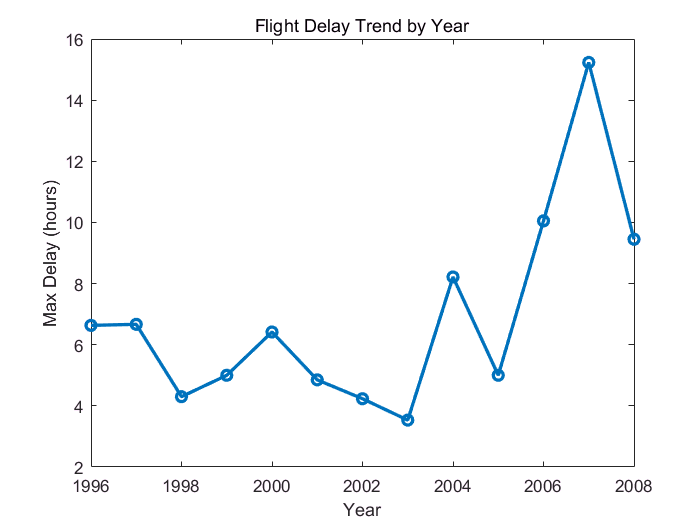

year = 1996:2008 ;     
mdelayInHours = mdelay/60; % Convert to hours
plot(year,mdelayInHours,'-o','LineWidth',2);
xlabel('Year')
ylabel('Max Delay (hours)')
title('Flight Delay Trend by Year')

A similar processing of the datastore can be used with the MapReduce framework in MATLAB®. For more information, see [docid:matlab_examples.example-ex52301769](docid:matlab_examples.example-ex52301769).